clear;
cs = crystalSymmetry('cubic');
ss = specimenSymmetry('mmm');

## Creating the grid about an ideal orientation For example Brass : 35,45,0.

phi1_id = 90;
phi_id = 27;
phi2_id = 45;
range = 20;
spacing = 5;
eul_ini = grid2euler(phi1_id, phi_id, phi2_id,range,spacing);



Running vpsc.exe from matlab

system('vpscnew.exe > NUL')

ans = 0

filename = 'TEX_PH1.OUT'; % this is the standard out file name of vpsc
% system('vpscnew.exe > myoutputfile.txt') %to save the output to the file 'my...txt'


Incase one wants to just input the vpsc out file

% prompt = 'The VPSC o/p euler angle file name without .txt extension \n';
% name = input(prompt);
% filename = [name, '.OUT']; 


% The final orientation after lattice spin 
%To be provided from vpsc

eul_fin = import_eul_fin(filename);%, startRow, endRow);


## **Calculating the differential**


o_ini = orientation('Euler',eul_ini,cs,ss);%.project2FundamentalRegion;
o_fin = orientation('Euler',eul_fin,cs,ss);%.project2FundamentalRegion;

% del_phi1 = (o_fin.phi1 - o_ini.phi1)/degree;
% del_Phi = (o_fin.Phi - o_ini.Phi)/degree;
% del_phi2 = (o_fin.phi2 - o_ini.phi2)/degree;

del_phi1 = (eul_fin(:,1) - eul_ini(:,1))/degree;
del_Phi = (eul_fin(:,2) - eul_ini(:,2))/degree;
del_phi2 = (eul_fin(:,3) - eul_ini(:,3))/degree;
del_eul = [del_phi1, del_Phi, del_phi2]

del_eul =    -4.3900    0.7500    3.6200
   -4.8400    0.8000    4.2900
   -4.1200    0.2700    3.8600
   -1.5500   -0.7300    1.6900
    2.4500   -1.3200   -1.9100
    1.9800   -1.3300   -1.4700
    0.7700   -1.2200   -0.4700
   -0.1300   -1.1700    0.2800
   -0.4100   -1.2000    0.5900
   -2.7400    1.4200    1.1700


div_scaler = abs(del_eul(:,1))+abs(del_eul(:,2))+abs(del_eul(:,3));
J=find(del_phi1 > 180); del_phi1(J)=360-del_phi1(J);
J=find(del_Phi > 180); del_Phi(J)=360-del_Phi(J);
J=find(del_phi2 > 180); del_phi2(J)=360-del_phi2(J);


## **Plotting 3D field**

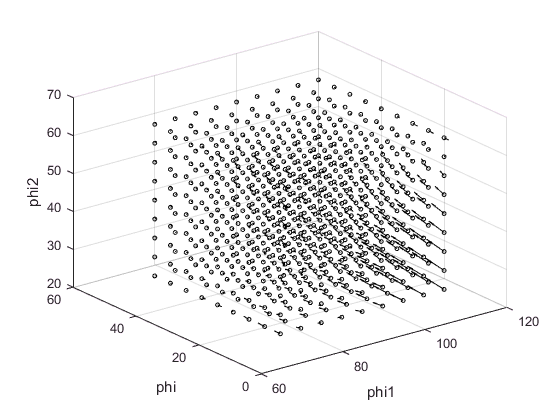

    
q = quiver3(eul_ini(:,1)/degree,eul_ini(:,2)/degree,eul_ini(:,3)/degree,del_phi1,del_Phi,del_phi2);
 xlabel('phi1');
 ylabel('phi');
 zlabel('phi2');
% q.xlabel(eul(1));
% q.ylabel(eul(2));
% q.xlabel(eul(3));
c = q.Color;
q.Color = 'black';
q.MaxHeadSize = 0.2;
q.AutoScaleFactor = 2;
q.Marker = 'o';
q.MarkerSize = 3;

## **Plotting Sections**

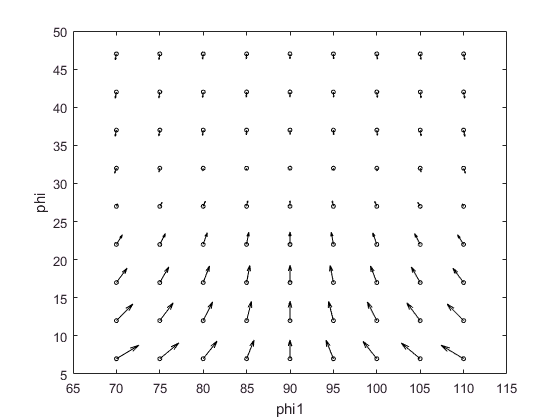

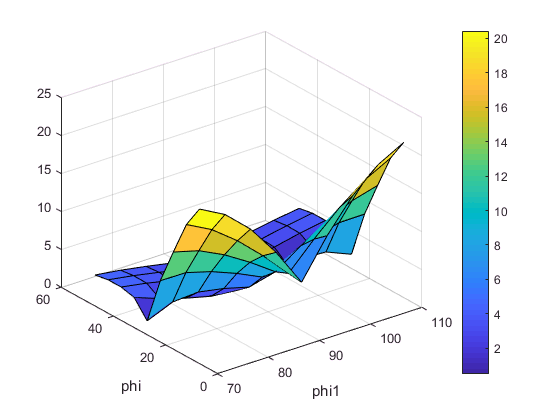

prompt = 'Which section you want? \n For phi1 section enter 1\n For Phi section enter 2 and for phi2 section enter 3 \n';
section = input(prompt);
secn_set = eul_ini;
secn_set(:,section) = [];
secn_deleul = del_eul;
secn_deleul(:,section) = [];
eul = ["phi1","phi" ,"phi2"];
eul(section) = [];
prompt = 'Please enter the section angle e.g. 45 \n ';
ang = input(prompt);
J1=find(eul_ini(:,section)== ang*degree); 
if isempty(J1), disp('the section does not exist in the list'); 
else
    q1 = quiver(secn_set(J1,1)/degree,secn_set(J1,2)/degree,secn_deleul(J1,1),secn_deleul(J1,2));
%     figure;
%     dv = surf( eul_ini(J1,1)/degree,eul_ini(J1,2)/degree,div_scaler(J1));
q1.Color = 'black';
q1.MaxHeadSize = 0.2;
q1.AutoScaleFactor = 0.5;
q1.Marker = 'o';
q1.MarkerSize = 3;
 xlabel(eul(1));
 ylabel(eul(2));
 
 figure;
 xx1 = reshape(secn_set(J1,1),9,9);
yy1  = reshape(secn_set(J1,2),9,9);
zz1 = reshape(div_scaler(J1,1),9,9);
dv = surf( xx1/degree,yy1/degree,abs(zz1));
 xlabel(eul(1));
 ylabel(eul(2));
 colorbar;
end

Reconvert

% 
% xx1 = reshape(secn_set(J1,1),9,9);
% yy1  = reshape(secn_set(J1,2),9,9);
% zz1 = reshape(div_scaler(J1,1),9,9);
% dv = surf( xx1/degree,yy1/degree,zz1);